# Problem set # 5

#### 1. Implementation of Breeden-Litzenberger:

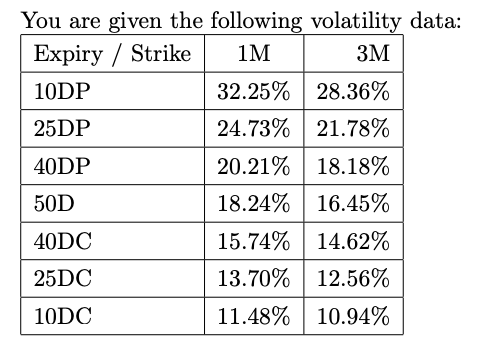

You also know that the current stock price is 100, the risk-free rate is 0, and the asset pays no dividends.

NOTE: The table of strikes is quoted in terms of Deltas, where the DP rows indicate ”X Delta Puts” and the DC rows indicate ”X Delta Calls”.

clear;clc;
S = 100; r = 0;

(a) Using the table of quoted (Black-Scholes) Deltas and volatilities, extract a table of strikes corresponding to each option.

T1 = 1/12; T2 = 3/12; T =[T1, T2];
vol_T1 = [0.3225, 0.2473, 0.2021, 0.1824, 0.1574, 0.1370, 0.1148]';
vol_T2 = [0.2836, 0.2178, 0.1818, 0.1645, 0.1462, 0.1256, 0.1094]';
vol = [vol_T1, vol_T2];
delta = [1-0.1, 1-0.25, 1-0.4, 0.5, 0.4, 0.25, 0.1]'; % delta or 1 + delta

    for call option, delta = N(d1); for put option, delta = N(d1) - 1. where   $d_1 =\frac{\ln \frac{S_0 }{K}+\left(r+\frac{\sigma^2 }{2}\right)T}{\sigma \sqrt{T}}$

    So, for call option, $K=\;e^{\mathrm{ln}S_0 -N^{-1} \left(\Delta \right)\sigma \sqrt{T}+\left(r+\frac{\sigma^2 }{2}\right)T}$; for put option, $K=\;e^{\ln S_0 -N^{-1} \left(1+\Delta \right)\sigma \sqrt{T}+\left(r+\frac{\sigma^2 }{2}\right)T}$

K_T1 = exp(log(S)-norminv(delta).*vol_T1*sqrt(T1)+(r+vol_T1.^2/2)*T1)'

K_T1 =    89.1388   95.5421   98.7006  100.1387  101.2623  102.7838  104.3958


K_T2 = exp(log(S)-norminv(delta).*vol_T2*sqrt(T2)+(r+vol_T2.^2/2)*T2)'

K_T2 =    84.2257   93.4707   98.1280  100.3388  102.1418  104.5327  107.4222


K = [K_T1', K_T2'];

(b) Choose an interpolation scheme that defines the volatility function for all strikes, σ(K).

    I choose cubic(pchip) interpolation.

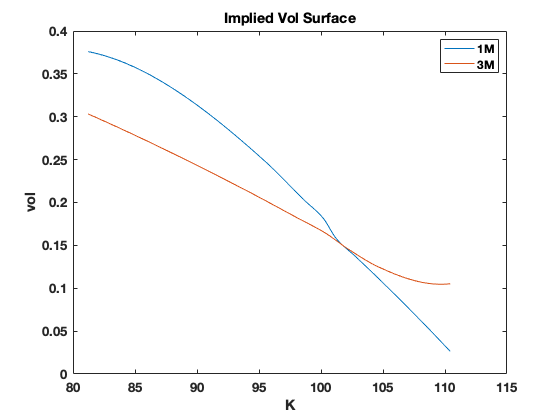

% Define sample strike prices for the interpolation.
extrapThresh = 3;
fineK = linspace(min(min(K_T1),min(K_T2))-extrapThresh, ...
                 max(max(K_T1),max(K_T2))+extrapThresh, 500).';
% Preallocate space for the results.
sigmaInterp = NaN(numel(fineK), numel(T));
for i = 1:numel(T)
    sigmaInterp(:, i) = interp1(K(:,i), vol(:,i), fineK, 'pchip', 'extrap');
end
myplot1(fineK, sigmaInterp(:, 1), fineK, sigmaInterp(:, 2))

(c) Extract the risk neutral density for 1 & 3 month options. Comment on the differences between the two distributions. Is it what you would expect?

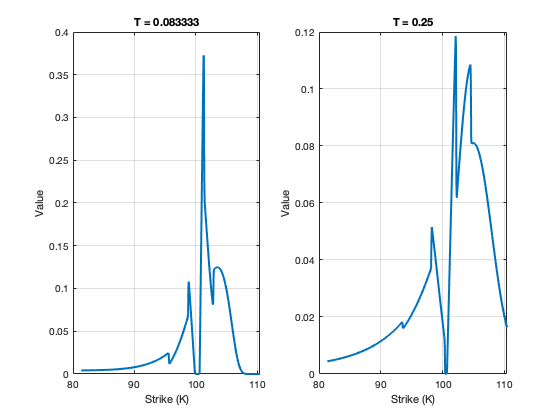

% bs prices
prc = NaN(size(sigmaInterp));
for i = 1:numel(T)    
    prc(:, i) = blsprice(S, fineK, r, T(i), sigmaInterp(:, i));
end

approxPDFs = blrnd(prc, fineK, r, T);

myplot2(approxPDFs, fineK, T);

    Risk neutral density of 3M is much less concentrated compared to that of 1M. That's what I expect.

(d) Extract the risk neutral density for 1 & 3 month options using a constant volatility equal to the 50D volatility. Contrast these densities to the densities obtained above.

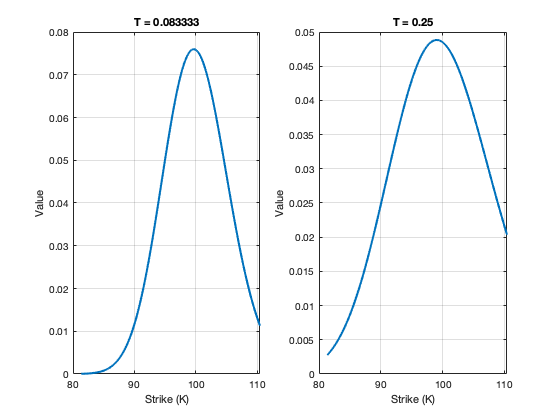

% bs prices
prc = NaN(size(sigmaInterp));
vol_50D = [vol_T1(4),vol_T2(4)];
for i = 1:numel(T)    
    prc(:, i) = blsprice(S, fineK, r, T(i), vol_50D(:, i));
end

approxPDFs2 = blrnd(prc, fineK, r, T);

myplot2(approxPDFs2, fineK, T);

        These two risk neutral densities look much more reasonable compared to last two, since implied vol generated by spline interpolation might be strange at the second derivative. However, the constant vol makes the density more normal and the shape consistent between different maturities.

(e) Price the following European Options using the densities you constructed in (1c). 

i. 1M European Digital Put Option with Strike 110. 

ii. 3M European Digital Call Option with Strike 105. 

iii. 2M European Call Option with Strike 100.

    for European options, the price formula is $\mathrm{price}=E_Q \left\lbrack e^{-\textrm{rT}} \mathrm{Payoff}\left(S_T ,K\right)\right\rbrack$:

% i
pdf_k = fineK(3:length(fineK));
pdf_1m = approxPDFs(:,1);
pdf_3m = approxPDFs(:,2);
pdf_2m = (pdf_1m + pdf_3m) / 2;
prc1 = 1 * sum(pdf_1m(pdf_k <= 110)./sum(pdf_1m))

prc1 = 1.0000

prc2 = 1 * sum(pdf_3m(pdf_k >= 105)./sum(pdf_3m))

prc2 = 0.3045

prc3 = sum((pdf_k(pdf_k >= 100) - 100) .* pdf_2m(pdf_k >= 100)./sum(pdf_2m))

prc3 = 2.6873

#### 1. Calibration of Heston Model:

Recall that the Heston Model is defined by the following system of SDE’s:


$$dS_t =rS_t \mathrm{dt}+\sqrt{\nu_t }S_t dW_t^1$$



$$d\nu_t =\kappa \left(\theta -\nu_t \right)\mathrm{dt}+\sigma \sqrt{\nu_t }dW_t^2$$
 


$$\mathrm{Cov}\left(dW_t^1 ,dW_t^2 \right)=\rho \mathrm{dt}$$


Recall also that the characteristic function for the Heston Model is known to be:


$$\omega \left(u\right)=\frac{\mathrm{exp}\left(\mathrm{iuln}S_0 +\mathrm{iu}\left(r-q\right)t+\frac{\kappa \theta t\left(\kappa -i\rho \sigma u\right)}{\sigma^2 }\right)}{{\left(\mathrm{cosh}\frac{\lambda t}{2}+\frac{\kappa -i\rho \sigma u}{\lambda }\mathrm{sinh}\frac{\lambda t}{2}\right)}^{\frac{2\kappa \theta }{\sigma^2 }} }$$



$$\Phi \left(u\right)=\omega \left(u\right)\mathrm{exp}\left(\frac{-\left(u^2 +\mathrm{iu}\right)\nu_0 }{\lambda \mathrm{coth}\frac{\lambda t}{2}+\kappa -i\rho \sigma u}\right)$$



$$\lambda =\sqrt{\sigma^2 \left(u^2 +\mathrm{iu}\right)+{\left(\kappa -i\rho \sigma u\right)}^2 }$$


See the attached spreadsheet for options data. r = 1.5%, q = 1.77%, S0 = 267.15.

Consider the given market prices and the following equal weight least squares minimization function:

where$\tilde{c} \left(\tau ,K,\overrightarrow{p} \right)$is the FFT based model price of a call option with expiry τ and strike K.

clear;clc
load optdata
r = 0.015; q = 0.0177; S = 267.15;

(a) Check the option prices for arbitrage. Are there arbitrage opportunities at the mid? How about after accounting for the bid-ask spread? Remove any arbitrage violations from the data.

T = unique(optdata.expT);

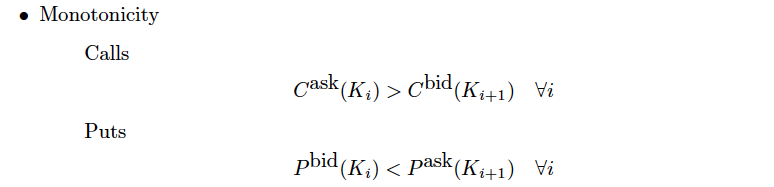

for i = 1:numel(T)
    idx = optdata.expT == T(i);
    tempK = optdata.K(idx);
    tempCask = optdata.call_ask(idx);
    tempCbid = optdata.call_bid(idx);
    tempPbid = optdata.put_bid(idx);
    tempPask = optdata.put_ask(idx);
    % check calls and puts
    check_mono = NaN(length(tempK)-1,2);
    for j = 1:length(tempK)-1
        check_mono(j,1) = tempCask(j) > tempCbid(j+1);
        check_mono(j,2) = tempPbid(j) < tempPask(j+1);
    end
    sprintf('Maturity:%.4f Monotonicity requirement for Calls: %d; Puts: %d',...
        T(i), all(check_mono(:,1)), all(check_mono(:,2)))
end

ans = 'Maturity:0.1342 Monotonicity requirement for Calls: 1; Puts: 1'

ans = 'Maturity:0.3833 Monotonicity requirement for Calls: 1; Puts: 1'

ans = 'Maturity:0.5558 Monotonicity requirement for Calls: 1; Puts: 1'

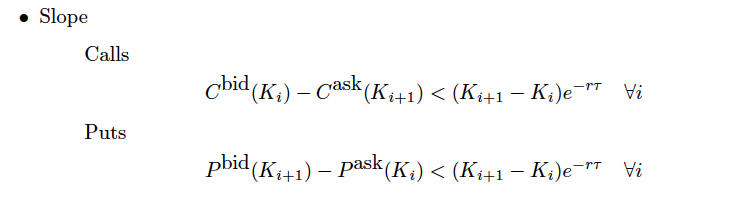

for i = 1:numel(T)
    idx = optdata.expT == T(i);
    tempK = optdata.K(idx);
    tempCask = optdata.call_ask(idx);
    tempCbid = optdata.call_bid(idx);
    tempPbid = optdata.put_bid(idx);
    tempPask = optdata.put_ask(idx);
    % check calls and puts
    check_slope = NaN(length(tempK)-1,2);
    for j = 1:length(tempK)-1
        check_slope(j,1) = tempCbid(j) - tempCask(j+1) < (tempK(j+1) - tempK(j))*exp(-r*T(i));
        check_slope(j,2) = tempPbid(j+1) - tempPask(j) < (tempK(j+1) - tempK(j))*exp(-r*T(i));
    end
    sprintf('Maturity:%.4f Slope requirement for Calls: %d; Puts: %d',...
        T(i), all(check_slope(:,1)), all(check_slope(:,2)))
end

ans = 'Maturity:0.1342 Slope requirement for Calls: 1; Puts: 1'

ans = 'Maturity:0.3833 Slope requirement for Calls: 1; Puts: 1'

ans = 'Maturity:0.5558 Slope requirement for Calls: 1; Puts: 1'

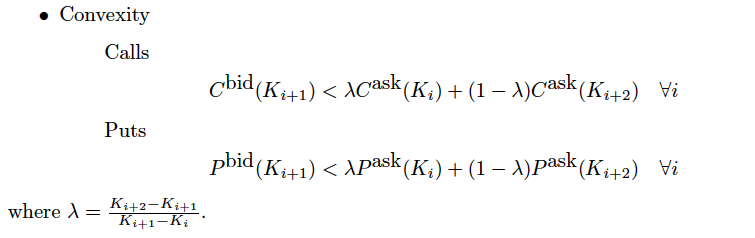

for i = 1:numel(T)
    idx = optdata.expT == T(i);
    tempK = optdata.K(idx);
    tempCask = optdata.call_ask(idx);
    tempCbid = optdata.call_bid(idx);
    tempPbid = optdata.put_bid(idx);
    tempPask = optdata.put_ask(idx);
    % check calls and puts
    check_conv = NaN(length(tempK)-2,2);
    for j = 1:length(tempK)-2
        lambda = (tempK(j+2) - tempK(j+1)) / (tempK(j+2) - tempK(j));
        check_conv(j,1) = tempCbid(j+1) < lambda * tempCask(j) + (1-lambda) * tempCask(j+2);
        check_conv(j,2) = tempPbid(j+1) < lambda * tempPask(j) + (1-lambda) * tempPask(j+2);
    end
    sprintf('Maturity:%.4f Convexity requirement for Calls: %d; Puts: %d',...
        T(i), all(check_conv(:,1)), all(check_conv(:,2)))
end

ans = 'Maturity:0.1342 Convexity requirement for Calls: 1; Puts: 1'

ans = 'Maturity:0.3833 Convexity requirement for Calls: 1; Puts: 1'

ans = 'Maturity:0.5558 Convexity requirement for Calls: 1; Puts: 1'

(b) Using the FFT Pricing code from your last homework, find the values of κ, θ, σ, ρ and ν0 that minimize the equal weight least squared pricing error. You may choose the starting point and upper and lower bounds of the optimization. You may also choose whether to calibrate to calls, puts, or some combination of the two. 

NOTE: In R, the optimx function can be used to perform this optimization, which has a parameter named method which can be set to Nelder-Mead. Note also that you are given data for multiple expiries, each of which should use the same parameter set, but will require a separate call to the FFT algorith.

% function mse = call_hes(kappa, theta, sigma, rho, v0, r, s, t, q, k, call)
x0 = [0.7, 0.1, 0.2, -0.4, 0.08];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0,0,0,-1,0];
ub = [10,1,1,1,1];
% call_hes(x0, r, S, T(i), q, tempK, tempCbid)
for i = 1:numel(T)
    idx = optdata.expT == T(i);
    tempK = optdata.K(idx);
    tempCask = optdata.call_ask(idx);
    tempCbid = optdata.call_bid(idx);
    f = @(x)call_hes(x, r, S, T(i), q, tempK, tempCbid, tempCask);
    x = fmincon(f,x0,A,b,Aeq,beq,lb,ub)
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



x =     0.0005    0.1836    0.9999   -0.8781    0.0459



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



x =     1.2984    0.0217    1.0000   -0.7880    0.0597



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



x =     1.7944    0.0004    1.0000   -0.7940    0.0916


(c) Try several starting points and several values for the upper and lower bounds of your parameters. Does the optimal set of parameters change? If so, what does this tell you about the stability of your calibration algorithm?

% function mse = call_hes(kappa, theta, sigma, rho, v0, r, s, t, q, k, call)
x0 = [0.1, 0.8, 0.5, 0.4, 0.18];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0,0,0,-1,0];
ub = [5,1,1,1,1];
for i = 1:numel(T)
    idx = optdata.expT == T(i);
    tempK = optdata.K(idx);
    tempCask = optdata.call_ask(idx);
    tempCbid = optdata.call_bid(idx);
    f = @(x)call_hes(x, r, S, T(i), q, tempK, tempCbid, tempCask);
    x = fmincon(f,x0,A,b,Aeq,beq,lb,ub)
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



x =     0.0005    0.1824    0.9999   -0.8781    0.0459



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



x =     0.5942    0.0926    0.9781   -0.7975    0.0469



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



x =     1.7886    0.0007    1.0000   -0.7942    0.0913


    The calibration is not sensitive to intial values when we set the parameters' bounds according to their economic meaning. However, If we allow these parameters to be strange, results can be quite different.

(d) Instead of applying an equal weight to each option consider the following function which makes the weights inversely proportional to the quoted bid-ask spread:

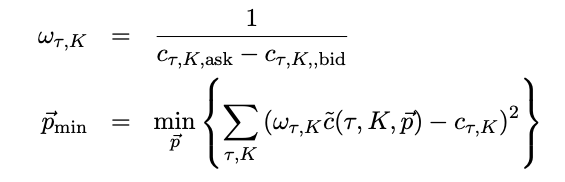

where as before $\tilde{c} \left(\tau ,K,\overrightarrow{p} \right)$ is the FFT based model price of a call option with expiry τ , strike K. Repeat the calibration with this objective function and comment on how this weighting affects the optimal parameters.

x0 = [0.7, 0.1, 0.2, -0.4, 0.08];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0,0,0,-1,0];
ub = [10,1,1,1,1];
for i = 1:numel(T)
    idx = optdata.expT == T(i);
    tempK = optdata.K(idx);
    tempCask = optdata.call_ask(idx);
    tempCbid = optdata.call_bid(idx);
    f = @(x)call_hes2(x, r, S, T(i), q, tempK, tempCbid, tempCask);
    x = fmincon(f,x0,A,b,Aeq,beq,lb,ub)
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

x =     0.0000    0.4574    1.0000   -0.9423    0.0000



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

x =     0.0000    0.0284    0.6380   -0.0544    0.0000



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



x =     0.0689    0.0000    0.1338    1.0000    0.0010


    The weights affect values of parameters in the sense that It emphasizes more to the points with lower bid-ask spread by giving them more weights. By this consideration of liquidity, we should come up with different parameters of heston model.

#### 3. Hedging Under Heston Model: 

Consider a 3 month European call with strike 275 on the same underlying asset.

% let's use parameters from first calibration.
x0 = [0.59, 0.09, 0.98, -0.8, 0.05];
kappa=x0(1);theta=x0(2);sigma=x0(3);rho=x0(4);v0=x0(5);
% 3 month European call with strike 275.
t = 3 / 12;
k = 275;

(a) Calculate this option’s Heston delta using finite differences. That is, calculate a first order central difference by shifting the asset price, leaving all other parameters constant and re-calculating the FFT based Heston model price at each value of S0.

shift_S = [S-10^10*eps, S+10^10*eps];
hes_c = NaN(1, length(shift_S));
for i = 1:length(shift_S)
    par = struct(...
    'rf', r, 'q', q, 'x0', log(shift_S(i)), 'v0', v0, 'kappa', kappa, ...
    'theta', theta, 'sigma', sigma, 'rho', rho);
    aux.x0 = par.x0;
    aux.N = 1024;
    aux.K = k;
    aux.damp = 1.5;
    cfHes = @(u) cflib(u, t, par, 'Heston');
    [hes_c(i), ~] = cf2call(cfHes, aux);
end
hes_delta = (hes_c(2) - hes_c(1)) / (shift_S(2) - shift_S(1))

hes_delta = 0.5282

i. Compare this delta to the delta for this option in the Black-Scholes model. Are they different, and if so why? If they are different, which do you think is better and why? Which would you use for hedging?

[bs_delta, ~] = blsdelta(S, k, r, t, sqrt(theta), q)

bs_delta = 0.4492

    Yes, they're different. because of difference between bs model and heston model. In heston model, volatility is varying, d1 in psi(d1) is not constant over time, causing a different delta w.r.t. the one from bs model. I would prefer using delta derived from heston model, because the assumption of time-varying volatility is more practical.

ii. How many shares of the asset do you need to ensure that a portfolio that is long one unit of the call and short x units of the underlying is delta neutral?

    According to delta from heston model which is about 0.53 in this case, I need to short 0.53 shares of underlying when I long one unit of the call.

(b) Calculate the vega of this option numerically via the following steps:

i. Calculate the Heston vega using finite differences. To do this, shift θ and ν0 by the same amount and calculate a first order central difference leaving all other parameters constant and re-calculating the FFT based Heston model price at each value of θ and ν0.

shift_val = 2 * 10^10*eps;
shift_theta = [theta-shift_val/2,theta+shift_val/2];
shift_v0 = [v0-shift_val/2,v0+shift_val/2];
hes_c2 = NaN(1, length(shift_theta));
for i = 1:length(shift_theta)
    par = struct(...
    'rf', r, 'q', q, 'x0', log(S), 'v0', shift_v0(i), 'kappa', kappa, ...
    'theta', shift_theta(i), 'sigma', sigma, 'rho', rho);
    aux.x0 = par.x0;
    aux.N = 1024;
    aux.K = k;
    aux.damp = 1.5;
    cfHes = @(u) cflib(u, t, par, 'Heston');
    [hes_c2(i), ~] = cf2call(cfHes, aux);
end
hes_vega = (hes_c2(2) - hes_c2(1)) / shift_val

hes_vega = 124.1164

ii. Compare this vega to the vega for this option in the Black-Scholes model. Are they different, and if so why?

bs_vega = blsvega(S, k, r, t, sqrt(theta), q)

bs_vega = 52.6564

    Yes, they are different. That's because by definition of heston model, with a negative rho, the direction of asset price is "opposite" to the direction of volatility, which means the vol would go up when price is plummeting, causing the option price more sensitive to vol.  